theta = linspace(20,200,1000);

%Create a vector k that is the correct scaled/translated erf function
% which is evaluated at the vector theta and is 0.31 for theta < 100,
% and is 0.19 for theta > 100
k = 0.25-erf(theta-100)*0.06

%Create a vector c that is the correct scaled/translated erf function
% which is evaluated at the vector theta and is 2800 for theta < 100,
% and is 2200 for theta > 100
c = 2500-erf(theta-100)*300

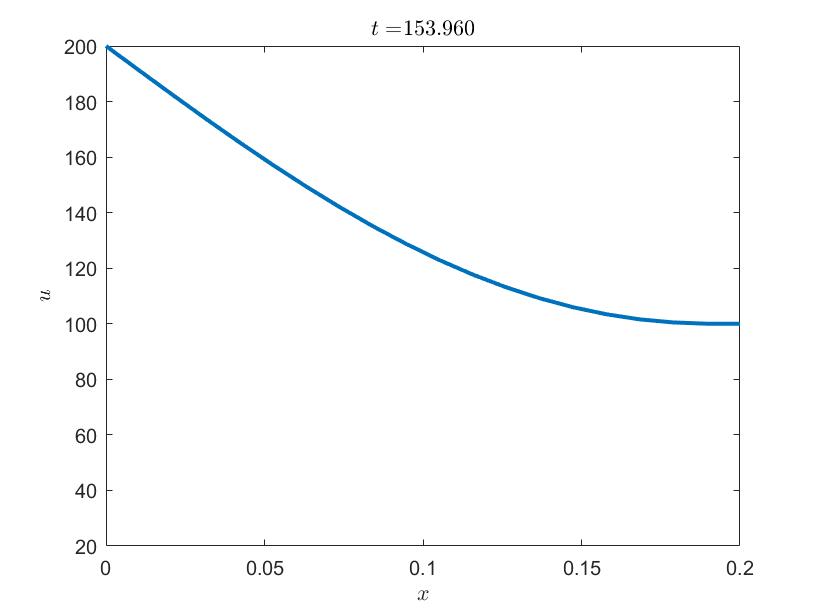

        2567



  154.0200



  100.0225



%Solve heat equation using forward time, centered space scheme
close all; clearvars;

%Define simulation parameters----------------------------------------------

%NOTE YOU WILL WANT TO EDIT THIS VALUE TO ANSWER THE QUESTION
L=0.2; %length of cake

x = linspace(0,L,20);     %Spatial grid
dt = 0.06;                 %Time step        
tMax = 200;                  %Simulation time (YOU MAY WANT TO MODIFY THIS!)
nu = 0.5;                  %Constant of proportionality


fInitial = @(x) 20*ones(1,20);               %Initial condition

%Run simulation------------------------------------------------------------
dx = x(2)-x(1);

u = fInitial(x); u(1) = 200; u(end) = u(end-1);

t = 0:dt:tMax;  %Time vector

k = @(u) ((0.19-0.31)/2)*erf(u-100) +(0.31-0.19)/2 + 0.19; %conductivity

c = @(u) ((2200-2800)/2)*erf(u-100) +(2800-2200)/2 + 2200; %capacity
tic
for i=1:length(t)
    u(i+1,1) = 200;  %Impose left B.C.
    for j=2:(length(x)-1)
    
        u(i+1,j) = u(i,j)+(dt/(2*dx^2*c(u(i,j))))*((k(u(i,j+1))+k(u(i,j)))*u(i,j+1)+(k(u(i,j-1))+k(u(i,j)))*u(i,j-1)-(k(u(i,j+1))+2*k(u(i,j))+k(u(i,j-1)))*u(i,j)); %Find solution at next time step
        
    end
    u(i+1,end) = u(i+1,end-1); %Impose right B.C.
    
    
    % Create the animation
    % First time through the main loop, create the plot
    % Subsequent times, update YData and title
    if i == 1
        u(i+1,end) = u(i+1,end-1); %Impose right B.C.
        %Plot solution
        p = plot(x,u(i+1,:),'linewidth',2); 
        xlabel('$x$','interpreter','latex') 
        ylabel('$u$','interpreter','latex')
        ylim([20,200]);
    else
        p.YData = u(i+1,:);        
    end
    title(['$t=$',num2str(t(i),'%.3f')],'interpreter','latex')
    drawnow limitrate
    
    %ADD SOME CODE HERE TO FIND THE TIME WHEN THE RIGHT END OF THE CAKE IS
    %BAKED
    if min(u(i+1,end-1) >= 100)
        disp(i);
        disp(i*0.06);
        disp(min(u(i+1,end-1)));
        break;
    end
end

toc

Elapsed time is 1.576098 seconds.
